## **Import the Data**

data = readtable("solar_weather.csv", "VariableNamingRule", "preserve");

## **Preprocessing**

% remove the hour and month columns

% specify the time format
data.Time.Format = "yyyy-MM-dd HH:mm:ss";
data.Time = [];
data.month = [];
data.hour = [];

data = rmmissing(data)

data = 196776×14 table
    Energy delta[Wh]    GHI    temp    pressure    humidity    wind_speed    rain_1h    snow_1h    clouds_all    isSun    sunlightTime    dayLength    SunlightTime/daylength    weather_type
    ________________    ___    ____    ________    ________    __________    _______    _______    __________    _____    ____________    _________    ______________________    ____________

           0             0     1.6       1021        100          4.9           0          0          100          0    

%Try to dummy code the weather_type and isSun later.
% data.weather_type = categorical(data.weather_type);
data.weather_type = []

data = 196776×13 table
    Energy delta[Wh]    GHI    temp    pressure    humidity    wind_speed    rain_1h    snow_1h    clouds_all    isSun    sunlightTime    dayLength    SunlightTime/daylength
    ________________    ___    ____    ________    ________    __________    _______    _______    __________    _____    ____________    _________    ______________________

           0             0     1.6       1021        100          4.9           0          0          100          0           0             450                 0           
           0

% data.isSun = categorical(data.isSun);
data.isSun = [];
data.("SunlightTime/daylength") = [];

% head(data, 200)
keep = data(1000:1020, :)

keep = 21×11 table
    Energy delta[Wh]    GHI     temp    pressure    humidity    wind_speed    rain_1h    snow_1h    clouds_all    sunlightTime    dayLength
    ________________    ____    ____    ________    ________    __________    _______    _______    __________    ____________    _________

           222             6    -5.9      1023         94          2.4           0           0          71            180            495   
           160           6.2    -3.5      1024         91          3.1           0           0          57            195            495   
            86             7    -3.5      1024

% save("preprocessed.mat", "data")

## **Standardize the Data**

numericVars = varfun(@isnumeric,data,'output','uniform');
dNum = data(:, numericVars);
meandNum = mean(dNum);
stddNum = std(dNum);
stdData = (dNum - meandNum) ./ stddNum;
data(:, numericVars) = stdData;

## **Save the Standard deviation and mean**

% stddNum = stddNum.("Energy delta[Wh]");
% meandNum = meandNum.("Energy delta[Wh]");

## **Partition the Data**

n = length(data.temp);
hpartition = cvpartition(n, "HoldOut", 0.4)

hpartition = Hold-out cross validation partition
   NumObservations: 196776
       NumTestSets: 1
         TrainSize: 118066
          TestSize: 78710

idTrain = training(hpartition);
idTest = test(hpartition)

idTest = 196776×1 logical array
   1
   0
   0
   0
   0
   1
   0
   0
   0
   0


dataTrain = data(idTrain, :);
dataTest = data(idTest, :);


%data.Properties.VariableNames

% plot(data.temp)

## **Train the Model**

mdl = fitrtree(dataTrain, "Energy delta[Wh]")

mdl =   RegressionTree
           PredictorNames: {'GHI'  'temp'  'pressure'  'humidity'  'wind_speed'  'rain_1h'  'snow_1h'  'clouds_all'  'sunlightTime'  'dayLength'}
             ResponseName: 'Energy delta[Wh]'
    CategoricalPredictors: []
        ResponseTransform: 'none'
          NumObservations: 118066


  Properties, Methods


mdlLoss = loss(mdl, dataTest)

mdlLoss = 0.1163

yPred = predict(mdl, dataTest)

yPred =    -0.5484
   -0.5484
   -0.5484
   -0.5484
   -0.5484
   -0.5484
   -0.5484
   -0.5484
   -0.5484
   -0.5348


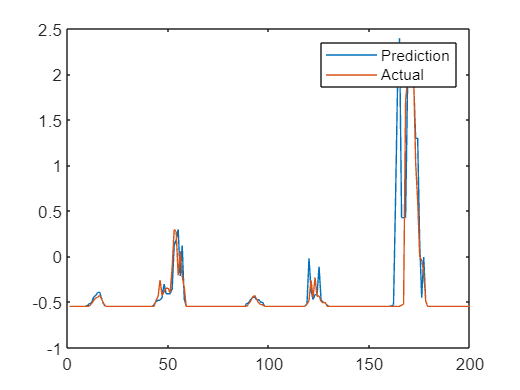



plot(yPred(1:200, 1))
hold on
plot(dataTest.("Energy delta[Wh]")(1:200, 1))
legend("Prediction", "Actual")
hold off


% YPred = (yPred * stddNum) + meandNum


saveLearnerForCoder(mdl, 'solarMdl');
save variables.mat stddNum meandNum -mat